# Wichmann and Hill 2001 - Fitting, sampling, and goodness of fit

January 4, 2021

clear; clc;
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Wichmann_Hill_2001')

## Figure 1

% data
sig_int = [0.8, 1.2, 1.4, 1.9, 2.1, 3.5];
p_corr1 = [0.5, 0.62, 0.77, 0.85, 1, 1];
p_corr2 = [0.5, 0.62, 0.77, 0.85, 1, 0.98];
% visualize 
figure; 
plot(sig_int, p_corr1, 'ko', 'markerfacecolor', 'b')
hold on 
plot(sig_int, p_corr2, 'r^', 'markerfacecolor', 'r')
xlim([0 4]); ylim([0.4 1.09])
xlabel('signal intensity'); ylabel('proprotion correct')
% fit 
weib = @(x,xdata) 0.5 + (1 - 0.5 - x(3)) * (1 - exp(-(xdata./x(1)).^x(2))); 
fmin_params1 = fmincon(@(x) nloglik(x(1), x(2), x(3), sig_int, p_corr1), [1.5 4 0], [], [], [], [], [0 0 0], [1e3 1e3 0.06]) % alpha, beta, lambda 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmin_params1 =     1.6346    3.9381    0.0000


fmin_params2 = fmincon(@(x) nloglik(x(1), x(2), x(3), sig_int, p_corr2), [1.5 4 0], [], [], [], [], [0 0 0], [1e3 1e3 0.06]) % alpha, beta, lambda 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmin_params2 =     1.6062    3.9750    0.0149


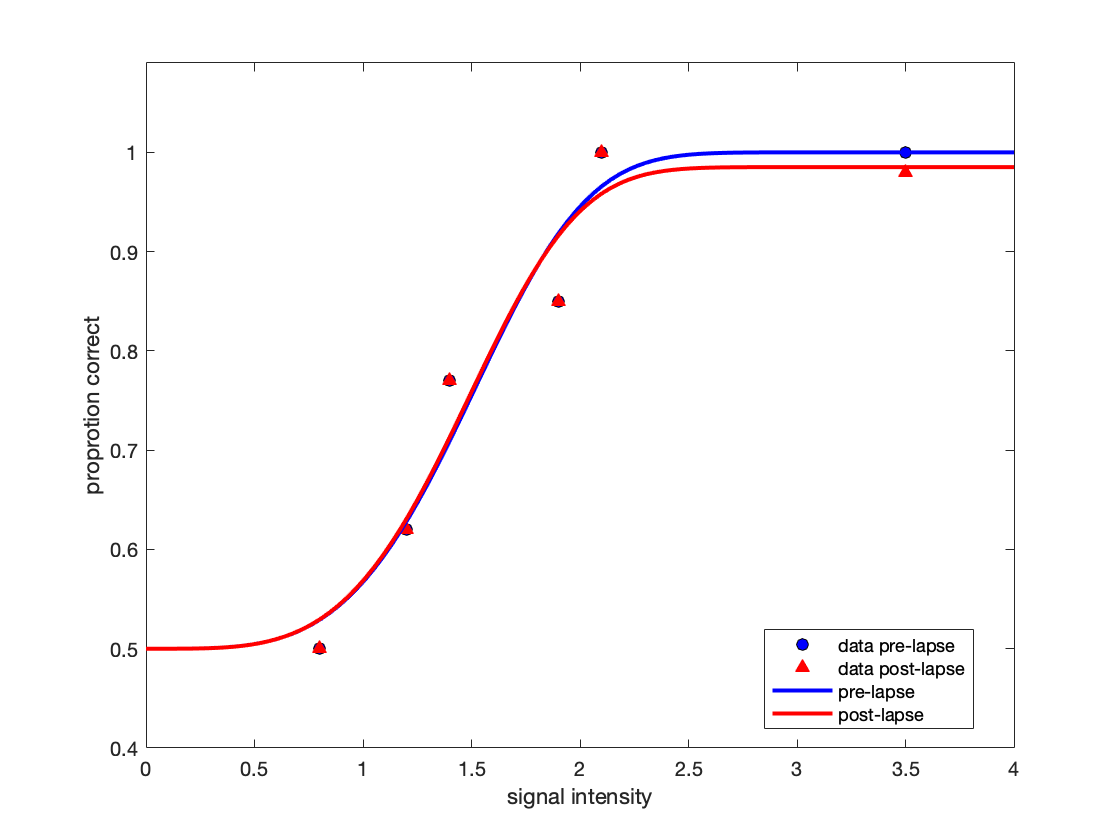

% fmin_params1 = fminsearch(@(x) nloglik(x(1), x(2), x(3), sig_int, p_corr1), [1.5 4 0]) % alpha, beta, lambda
% fmin_params2 = fminsearch(@(x) nloglik(x(1), x(2), x(3), sig_int, p_corr2), [1.5 4 0]) % alpha, beta, lambda 
% psi_fun_free = @(x,xdata) 0.5 + (1 - 0.5 - x(3)) * (1 - exp(-(xdata./x(1)).^x(2))); % alpha, beta, lambda
% psi_fun_fixed = @(x,xdata) 0.5 + (1 - 0.5 - x(3)) * (1 - exp(-(xdata./x(1)).^x(2))); % alpha, beta, lambda
% fit_free = lsqcurvefit(psi_fun_free, [2 4 0], sig_int, p_corr1)
% fit_fixed = lsqcurvefit(psi_fun_fixed, [2 4 0], sig_int, p_corr1)

xline = linspace(0, 4);
plot(xline, weib(fmin_params1, xline), 'b', 'linewidth', 2)
plot(xline, weib(fmin_params2, xline), 'r', 'linewidth', 2)
% plot(xline, psi_fun_free(fit_free, xline), 'k-', 'linewidth', 2)
% plot(xline, psi_fun_fixed(fit_fixed, xline), 'k--', 'linewidth', 2)
% title(sprintf('Parameters1 = alpha = %.3f; beta = %.3f; gamma = %.3f; lambda = %.3f\nParameters2 = alpha = %.3f; beta = %.3f; gamma = %.3f; lambda = %.3f', ...
%     fit_free(4), fit_free(3), fit_free(1), fit_free(2), fit_fixed(3), fit_fixed(2), fit_fixed(1), 0))

legend('data pre-lapse', 'data post-lapse', 'pre-lapse', 'post-lapse', 'location', 'best')

% Again with 4 free parameters 
% visualize 
figure; 
plot(sig_int, p_corr1, 'ko', 'markerfacecolor', 'b')
hold on 
plot(sig_int, p_corr2, 'r^', 'markerfacecolor', 'r')
xlim([0 4]); ylim([0.4 1.09])
xlabel('signal intensity'); ylabel('proprotion correct')
% fit 
weib = @(x,xdata) x(4) + (1 - x(4) - x(3)) * (1 - exp(-(xdata./x(1)).^x(2))); % alpha, beta, lambda, gamma
fmin_params1 = fmincon(@(x) nloglik_1(x(1), x(2), x(3), x(4), sig_int, p_corr1), [1.5 4 0 0.5], [], [], [], [], [0 0 0 0.5], [1e3 1e3 0.06 0.5]) 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmin_params1 =     1.6346    3.9381    0.0000    0.5000


fmin_params2 = fmincon(@(x) nloglik_1(x(1), x(2), x(3), x(4), sig_int, p_corr2), [1.5 4 0 0.5], [], [], [], [], [0 0 0 0.5], [1e3 1e3 0.06 0.5])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmin_params2 =     1.6062    3.9750    0.0149    0.5000


fmin_params3 = fmincon(@(x) nloglik_1(x(1), x(2), x(3), x(4), sig_int, p_corr1), [1.5 4 0 0], [], [], [], [], [0 0 0 0.5], [1e3 1e3 0 0.5])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fmin_params3 =     1.6346    3.9381         0    0.5000


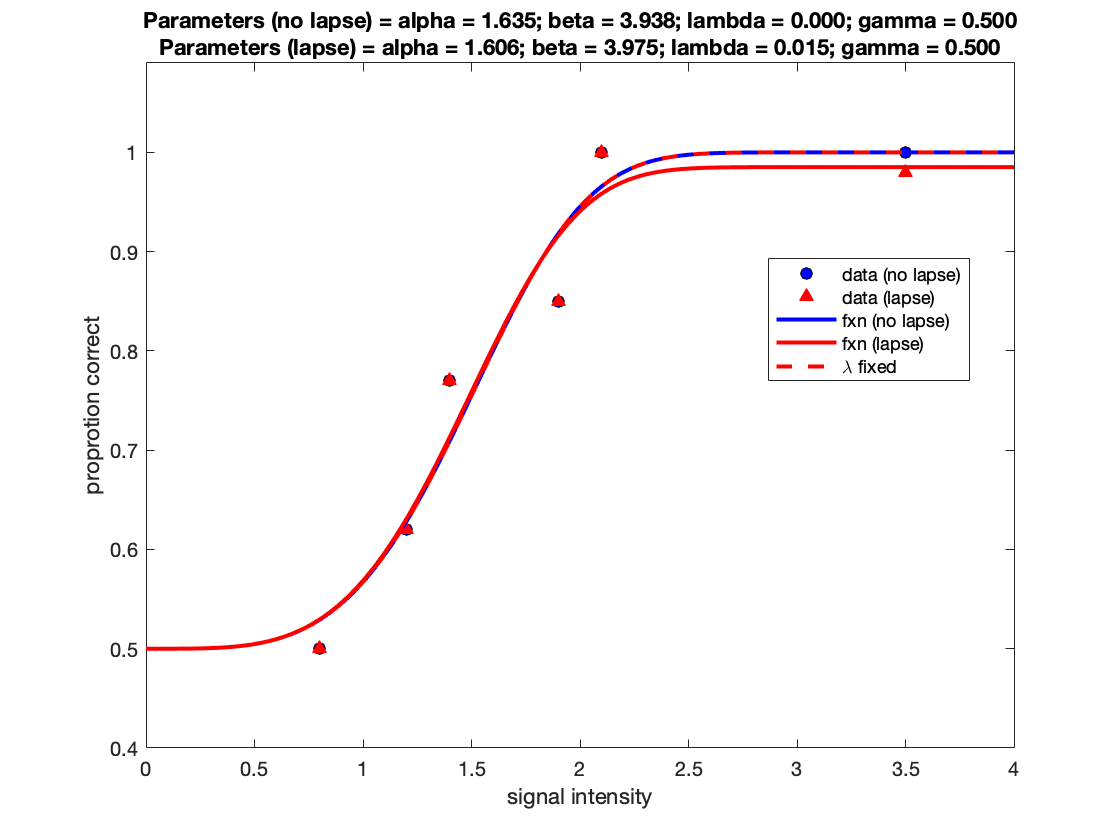

xline = linspace(0, 4);
plot(xline, weib(fmin_params1, xline), 'b', 'linewidth', 2)
plot(xline, weib(fmin_params2, xline), 'r', 'linewidth', 2)
plot(xline, weib(fmin_params3, xline), 'r--', 'linewidth', 2)
title(sprintf('Parameters (no lapse) = alpha = %.3f; beta = %.3f; lambda = %.3f; gamma = %.3f\nParameters (lapse) = alpha = %.3f; beta = %.3f; lambda = %.3f; gamma = %.3f', ...
    fmin_params1(1), fmin_params1(2), fmin_params1(3), fmin_params1(4), fmin_params2(1), fmin_params2(2), fmin_params2(3), fmin_params2(4)))

legend('data (no lapse)', 'data (lapse)', 'fxn (no lapse)', 'fxn (lapse)','\lambda fixed', 'location', 'best')

## Deviance

First derive equation 5 from 4. 

$D=2\log \left\lbrack \frac{L\left(\theta_{\max } ;y\right)}{L\left(\theta^{\wedge } ;y\right)}\right\rbrack =2\left\lbrack l\left(\theta_{\max } ;y\right)-l\left(\theta^{\wedge } ;y\right)\right\rbrack$              (4)

Note: Log rule: log(a - b) = log(a / b).

Let *k* denote # of x values (i.e. stimulus intensities), *n* denote # of trials at each x-value/stimulus intensiities, *y* denote probability from model fit (therefore $\psi \left(x;\theta_{\max } \right)$ = *y)*, *p* denote $\psi \left(x;\theta^{\wedge } \right)$. 

$\psi \left(x;\theta_{\max } \right)$ refers to a function where the number of parameters equals the number of data (i.e. a "perfect fit" where function goes through each data point). Therefore, we can just treat the data as this function. 


$$D=2\left\lbrack \sum_{i=1}^k \;\log \left(\frac{n_i }{y_i n_i }\right)+y_i n_i \;\log \;\psi \left(x_i ;\theta_{\max } \right)+\left(1-y_i \right)n_i \;\log \left(1-\psi \left(x;\theta_{\max } \right)\right)-\;\log \left(\frac{n_i }{y_i n_i }\right)+y_i n_i \;\log \;\psi \left(x_i ;\theta^{\wedge } \right)+\left(1-y_i \right)n_i \;\log \left(1-\psi \left(x;\theta^{\wedge } \right)\right)\right\rbrack$$
 

Simplify terms. 


$$D=2\left\lbrack \sum_{i=1}^k \;y_i n_i \log \left(\psi \left(x;\theta_{\max } \right)\right)--y_i n_i \log \left(\psi \left(x_i ;\theta^{\wedge } \right)\right)+\left(1-y_i \right)n_i \;\log \left(1-\psi \left(x_i ;\theta_{\max } \right)\right)-\left(1-y_i \right)n_i \log \left(1-\psi \left(x_i ;\theta^{\wedge } \right)\right)\right\rbrack$$


Simplify further.


$$D=2\;\sum_{i=1}^k y_i n_i \log \left(\frac{y_i }{p_i }\right)+\left(1-y_i \right)n_i \log \left(\frac{1-y_i }{1-p_{i\;} }\right)$$


n = 100;
for i = 1:length(sig_int)
    A = n * p_corr1(i) * log(p_corr1(i)/psi_fun_free(fit_free,sig_int(i)))
    B = n * (1-p_corr1(i))
    C = log((1 - p_corr1(i)) / (1 - psi_fun_free(fit_free,sig_int(i))))
    d(i) = A + B * C; 
end

A = 0.2717

B = 50

C = -0.0054

A = -2.4764

B = 38

C = 0.0688

A = 4.0209

B = 23

C = -0.1573

A = -5.6441

B = 15.0000

C = 0.4927

A = 4.9744

B = 0

C = -Inf

A = -0.6770

B = 0

C = -Inf

D = 2 * sum(d)

D = NaN

## Testing

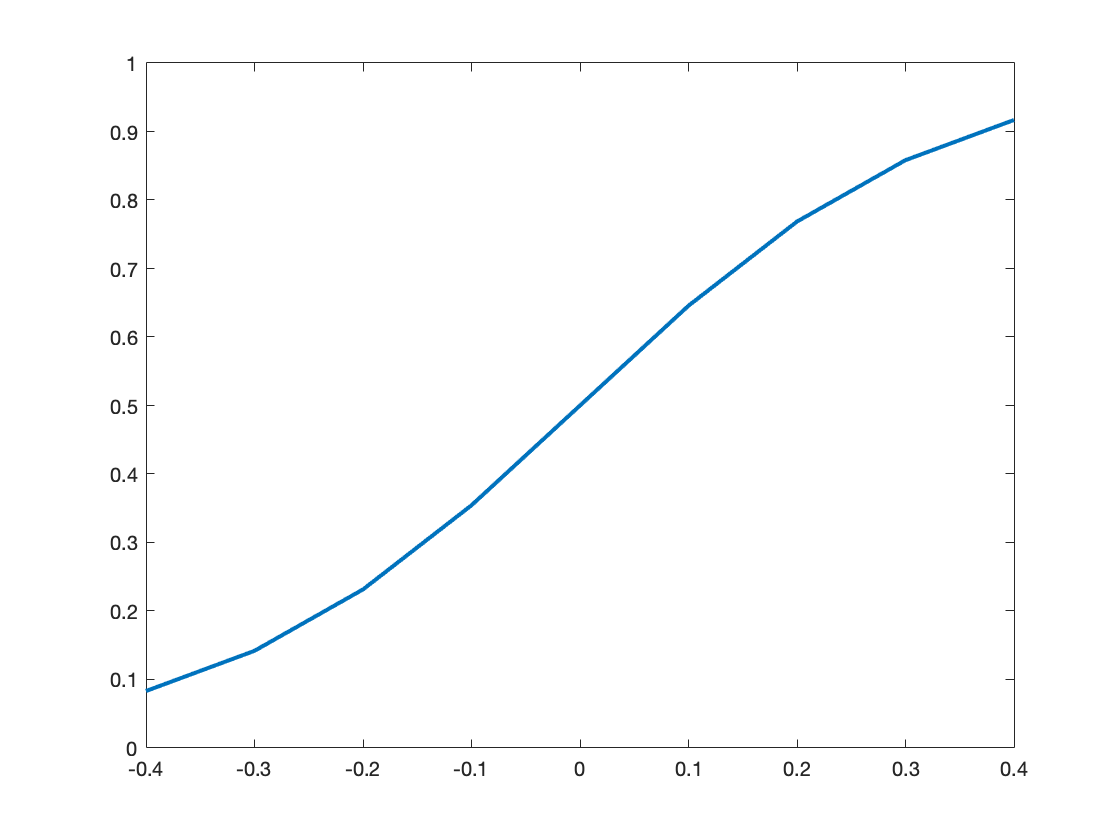

psi = @(x,xdata) x(4) + (1 - x(3) - x(4)) * (1 ./ (1 + exp(-x(1) * (xdata - x(2))))); % alpha, beta, lambda, gamma
intensity = -0.4:0.1:0.4;
figure;
plot(intensity, psi([6 0 0 0], intensity), 'linewidth', 2)

function nll = nloglik(alpha, beta, lambda, signal_intensity, p_correct)
% INPUTS:
% alpha: 

% OUTPUT:
% nll: negative log likelihood 



Deriving negative log likelihood from likelihood of a binomial distribution. 

Write out likelihood of a binomial distribution, where *n *denotes upper limit, *x *denotes probabilities from subject, and *p* denotes probabilities from model fit. 

$L\left(p;x\right)=\frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x}$                                (1)

Take the negative log of equation 1. 

$=-\log \left\lbrack \frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x} \right\rbrack$                                 (2)

Distribute the log. 

$=-\log \left(\frac{n!}{x!\left(n-x\right)!}\right)+\;\log \left(p^x \right)\;+\;\log \left({\left(1-p\right)}^{n-x} \right)$        (3)

Note: Log rule: log(a*b) = log(a) + log(b)

Remove constant, distribute exponents and negative sign. 

$=-\textrm{xlog}\left(p\right)-\left(n-x\right)\log \left(1-p\right)$                                     (4)

Note: Log exponent rule: log(a^b) = b*log(a)


% Create psychometric function (Weibull) 
I = 0.5 + (1 - 0.5 - lambda) * (1 - exp(-(signal_intensity./alpha).^beta)); 

% find nll 
nll = -sum(p_correct .* log(I) + (1 - p_correct) .* log(1 - I)); 

end
function nll = nloglik_1(alpha, beta, lambda, gamma, signal_intensity, p_correct)
% INPUTS:
% alpha: threshold / PSE (point of subjective equality)
% beta: slope / rate of change / heat
% lambda: lapse rate (probability of an incorrect response, which is
% independent of stimulus intensity) 
% gamma: guess rate (probability of a correct response when the stimulus is
% not detected by the underlying sensory mechanism)

% OUTPUT:
% nll: negative log likelihood 


Deriving negative log likelihood from likelihood of a binomial distribution. 

Write out likelihood of a binomial distribution, where *n *denotes upper limit, *x *denotes probabilities from subject, and *p* denotes probabilities from model fit. 

$L\left(p;x\right)=\frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x}$                                (1)

Take the negative log of equation 1. 

$=-\log \left\lbrack \frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x} \right\rbrack$                                 (2)

Distribute the log. 

$=-\log \left(\frac{n!}{x!\left(n-x\right)!}\right)+\;\log \left(p^x \right)\;+\;\log \left({\left(1-p\right)}^{n-x} \right)$        (3)

Note: Log rule: log(a*b) = log(a) + log(b)

Remove constant, distribute exponents and negative sign. 

$=-\textrm{xlog}\left(p\right)-\left(n-x\right)\log \left(1-p\right)$                                     (4)

Note: Log exponent rule: log(a^b) = b*log(a)


% Create psychometric function (Weibull) 
I = gamma + (1 - gamma - lambda) * (1 - exp(-(signal_intensity./alpha).^beta)); 

% find nll 
nll = -sum(p_correct .* log(I) + (1 - p_correct) .* log(1 - I)); 

end